clear;
load("Violine_example.mat");
%sound(example, Fs_example);

f = Fs_example*(0:(length(example)/2))/length(example);
X = fft(example);

P2 = abs(X/length(example));
P1 = P2(1:length(example)/2+1); 

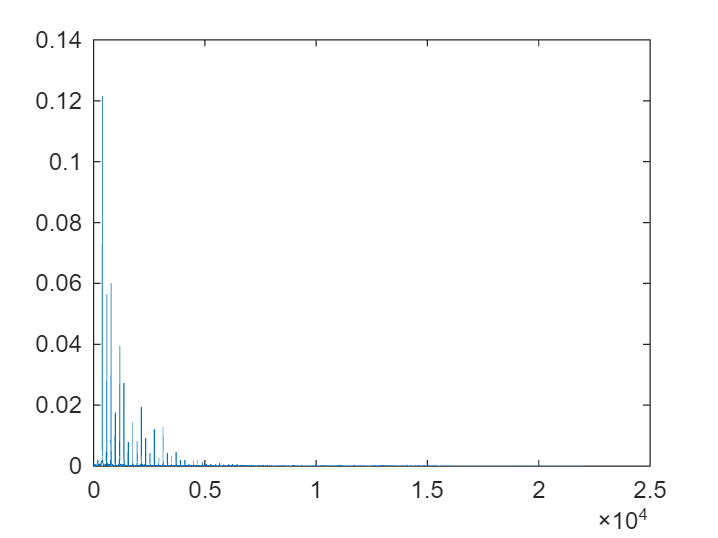

P1(2:end-1) = 2*P1(2:end-1);

plot(f, P1);

[maxValue, maxIndex] = max(P1);
disp("maxValue = " + maxValue);

maxValue = 0.12152


disp("maxIndex = " + (maxIndex-1));

maxIndex = 487



global Fs lengthOf1 m c_m;
Fs = 44100; % Samplerate
lengthOf1 = 0.8; % Dauer einer "ganzen Note" in Sekunden
m = [1 2 3 4 6 8 10 12 14 16 18 20 24]; % Vektor der implementierten Obertöne
c_m = [0.122 0.056 0.06 0.018 0.039 0.027 0.008 0.014 0.008 0.019 0.009 0.004 0.012]; 
mainVolume = 0.1;

output = makeTone(44, 0.5, mainVolume);
output = [output makeTone(47, 0.5, mainVolume)];
output = [output makeTone(51, 0.5, mainVolume)];
output = [output makeTone(51, 0.5, mainVolume)];
output = [output makeTone(51, 0.5, mainVolume)];
output = [output makeTone(49, 0.5, mainVolume)];
output = [output makeTone(52, 0.5, mainVolume)];
output = [output makeTone(51, 0.5, mainVolume)];
output = [output makeTone(49, 0.5, mainVolume)];
output = [output makeTone(47, 1.5, mainVolume)];
output = [output makePause(1/32)];
output = [output makeTone(49, 0.5, mainVolume)];
output = [output makeTone(51, 0.5, mainVolume)];
output = [output makeTone(47, 0.5, mainVolume)];
output = [output makeTone(44, 0.5, mainVolume)];
output = [output makeTone(47, 0.5, mainVolume)];
output = [output makeTone(49, 0.5, mainVolume)];
output = [output makeTone(46, 0.5, mainVolume)];
output = [output makeTone(44, 0.5, mainVolume)];
output = [output makeTone(42, 0.5, mainVolume)];
output = [output makeTone(44, 1.5, mainVolume)];

outputPlayer = audioplayer(output, Fs);
playblocking(outputPlayer);

function y = makePause(pauseLength)
    global Fs lengthOf1;
	y = zeros(1, floor(Fs * pauseLength * lengthOf1));
end